# Generating Surface Meshes and Calculating Metrics for a subset of dying cells

## Overview

This script generates cell surface meshes for a set of taste cells that are dying but that have not had their lysosomes segmented. The metrics calculated from these cells will be used for cell size analysis

Since these cells do not have their lysosomes, we did not add their information to the main idT table or their traces to the main VL table. Instead we created a separate table to organize the cell info and used that table to generate a separate VL table used only in this script.

Refer to the [generate_cellMesh_cellT.mlx](matlab:open('./generate_cellMesh_cellT.mlx')) script for more details on cell mesh generation. 

### REQUIREMENTS: 

- ManifoldPlus [https://github.com/hjwdzh/ManifoldPlus](https://github.com/hjwdzh/ManifoldPlus) 

- pyMeshFix: [https://pymeshfix.pyvista.org](https://pymeshfix.pyvista.org)

- MathWorks Lidar Toolbox

- MatGeom Toolbox (meshVolume function)

### DATA GENERATED

#### Mesh Files

OBJ files: Three different meshes generated for each cell trace and stored as OBJ files in the cell Meshes folder

- CELL_ID_as.obj - mesh created by MATLAB alphaShape function

- CELL_ID_mp.obj - watertight mesh created by ManifoldPlus

- CELL_ID_fx.obj - watertight mesh generated by pyMeshFix

Note: some cell traces that belonged to the same cell were saved with different Object names. For example, TB2_TCdying-01-apical_cw and  TB2_TCdying-01_cw are from the same cell. Meshes created from two different cell objects were saved by their ID name. In this case, TB_TCdying01.

#### MATLAB TABLES

**dyIDT** contains the imported data from the dying_list.csv file

**dyCellMeshT.mat** contains table variable information about the generated meshes. Each row in the table contains the data from one Cell. Columns in the table include

- Cell - CELL ID, unique identifier for a cell

- Type - taste cell type

- Health - early or late dying

- Polarity - apical direction of cell. 1 means keep default direction, -1 means invert

- AlphaRadius - setting used in alphaShape NaN means default value used)

- VolAS - volume of AlphaShape mesh

- VolMP - volume of Manifold Plus mesh

- VolFX - volume pyMeshFix

**dyingT.mat** contains the info on the cell mesh version that provides the best volume calculation (In some cases, the watertight mesh is less representative of the cell that the original AlphaShape mesh). This is manually decided by visual inspection. 

The columns in the dyingT table are as follows:

- Cell: Cell ID

- Type: Taste cell Type, x means unknown

- Health: early or late dying

- Volume, SurfaceArea - the volume and surface area of the manually selected mesh

- SAV: Surface to Volume ratio

- Filename: Name of the cell mesh file used for the volume calculations

NOTE: only run this script after running the [generate_cellMesh_cellT.mlx](matlab:open('./generate_cellMesh_cellT.mlx')) and generating the meshT table there.

## Set-up

clearvars -except paths
close all
clc

### Path to manifoldPlus

Update:

- reconstruct path: contains folder with Reconstruct Data

-  manifoldPlus path for your local installation (../ManifoldPlus/build/manifold)

paths.reconstruct = "/Users/ernesto/Documents/WORK/Research/Finger Lab/Dying Cell Project/reconstruct data";
paths.manifoldPlus = "/Users/ernesto/github/ManifoldPlus/build/manifold";

## Load Reconstruct Data and generate VL table

### Get Cell Dying ID Table

This table contains the names of a dying cells to be meshed

paths.dyingTableCSV="/Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/dying_list.csv";
dyIDT = get_table(paths.dyingTableCSV)

note:

- TB2_TCdying01, TB2_TCdying02, and TB3_TC01 are also in the Lysosome Dataset, so be sure to keep track of these objects (e.g. don't save TB3_TCo1 in dyCellMeshT)

- These cells were place here because of their apical bits, which I don't manage in the other script

### Set Load Table

Create a loadT table which contains the settings for import

- **load = true** means to process data from the indicated folder

- **load_last = true** means reload the last processed VL (much faster, but doesn't include any new traces)

contents = dir(paths.reconstruct);
contents(~[contents.isdir])=[];

dyIDT = 18×8 table
         Cell                    Object              Type    Health     TB    Dataset        Folder         Mesh
    _______________    __________________________    ____    _______    __    _______    _______________    ____

    "TB2_T2_14"        "TB2_T2Cell14_CM_LES"         II      healthy    3      DS2       "ROB_DS2"           0  
    "TB1_AP68"         "TB1_AP68_EM"                 III     early      1      TF21      "ROB_TF21_TB1"      0  
    "TB1_AP43"         "TB1_AP43_EM"                 II      early      1      TF21      "ROB_TF21_TB1"      0  
    "TB1_T2C05"        "TB1_t2cell05_CM_RKJ"         II      early      1      DS2       "ROB_DS2"           0  
    "TB1_T2C06"        "TB1_t2

contents(contains({contents.name},'.'))=[];
folderNames = string({contents.name}); % get Folder names from reconstruct folder
loadT = table(true(numel(contents),1), ...
    string({contents.name})', ...
    true(numel(contents),1), ...
    VariableNames=["Load" "Folder" "Load_Last"]);
loadT.Load = ismember(folderNames,unique(dyIDT.Folder))'; % is folder name found in didT?

loadT.Load_Last = [true; true; true; false; false] % manually select which folders to load_last

### Get Vertices of Cell traces

dyVL = getAllDyingVL(paths, dyIDT, loadT(loadT.Load,:));

## Generate Dying Cell Meshes

- Remember, no lysosomes in this dataset

- resets volume calc in dcmT (if already calculated)

dyCellMeshT = genDyingCellMesh(dyVL,dyIDT, paths); % dying cell meshT
disp(dyCellMeshT)

save(dyCellMeshT.Properties.UserData.filePath,"dyCellMeshT")

### Generate a subset

only those selected cells indicated

Use the mesh field in dyCellMeshT to pick which cells to mesh

### Load dyCellMeshT if needed

load(fullfile(paths.cellMesh, "dyCellMeshT.mat"),"-mat","dyCellMeshT")

loadT = 5×3 table
    Load         Folder         Load_Last
    _____    _______________    _________

    true     "Courtney_TF21"      true   
    true     "ROB_DS2"            true   
    true     "ROB_TF21_TB1"       true   
    false    "Ruibiao_DS2"        false  
    false    "TOM_TF21_tb2"       false  


## Inspect Cell Meshes

Once **generateCellMeshes** is complete, it is critical to inspect all of the meshes, especially those that have radically different volume calculations between the various methods.  

- Note: Most Cell Meshes appear to be well represented by the MP method. But on Occasion, you need to set a different method

### Step 1) Visualize Mesh

Check for orientation and / or holes. If it looks fine, you're done. Move onto the next cell. 

If there are any issues, proceed to the next step to update the mesh generation settings, and then re-visualize the cell (come back to this step)

dcmT_row = 13; % row in dcmT
hvwr = displayCellMeshes(dyCellMeshT.Cell(dcmT_row),paths.cellMesh);

- Copy the meshes 

### Step 2) Adjust settings and Recalculate Cell Meshes 

- if the cell is upside-down, change the Polarity setting to -1 

-  If there are holes in the mesh, adjust the Alpha Radius

cellName = dyCellMeshT.Cell(dcmT_row);

1. Courtney_TF21.

 **IMPORT COMPLETE** 
 Saved as: /Users/ernesto/Documents/WORK/Research/Finger Lab/Dying Cell Project/reconstruct data/Courtney_TF21/VerticesListdying.mat 
 Image Magnification: 0.0086 
 Section Thickness: 0.0850
2. ROB_DS2.

 **IMPORT COMPLETE** 
 Saved as: /Users/ernesto/Documents/WORK/Research/Finger Lab/Dying Cell Project/reconstruct data/ROB_DS2/VerticesListdying.mat 
 Image Magnification: 0.0075 
 Section Thickness: 0.0800
3. ROB_TF21_TB1.

 **IMPORT COMPLETE** 
 Saved as: /Users/ernesto/Documents/WORK/Research/Finger Lab/Dying Cell Project/reconstruct data/ROB_TF21_TB1/VerticesListdying.mat 
 Image Magnification: 0.0079 
 Section Thickness: 0.0850
dyVL saved as /Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/dyingVL.mat


polarity = -1;
aRadius = 1; % try values like 1-4. Or nan if base input wanted
dyCellMeshRowExcerpt = generateSingleCellMesh(dyVL,dyIDT, dyCellMeshT,paths, cellName, polarity, aRadius);

- The first output shows the previous settings

- The second output shows the updated settings

### Step 3) Update dyCellMeshT 

if you adjusted settings in step 2, run this code block to update the dyCellMeshT table with the updated values. Make that you update the best method to use for calculating the volume

dyCellMeshRowExcerpt.Method = "mp"

dyCellMeshT file found and loaded. Using this table for the analysis.
Row 9. TB1_AP43 found and meshed.
Row 10. TB1_AP68 found and meshed.
Row 11. TB1_T2C05 found and meshed.
Row 12. TB1_T2C06 found and meshed.
Row 13. TB1_T2C11 found and meshed.
Row 14. TB2_T2C-01 found and meshed.
Row 15. TB2_T2_14 found and meshed.


dyCellMeshT(dcmT_row,:) = dyCellMeshRowExcerpt

         Cell          Type    Health     Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX 
    _______________    ____    _______    ______    ________    ___________    ______    ______    ______

    "TB2_TCdying01"    x       late        "mp"        1            NaN        149.89     403.6    403.03
    "TB2_TCdying02"    x       late        "mp"        1            NaN        249.22    457.08    456.91
    "TB3_TC01"         x       late        "mp"        1            NaN        246.54    446.93    446.92
    "TB3_TC02"         II      early       "mp"        1            NaN        797.71    943.65    967.71
    "TB3_TC03"         III     early       "mp"        1 

### Step 4) Save your work

save(dyCellMeshT.Properties.UserData.filePath,"dyCellMeshT")

## Calculate Dying Cell Metrics

### load dyCellMeshT table if needed

load(fullfile(paths.cellMesh,"dyCellMeshT.mat"),"-mat","dyCellMeshT")

dcmT file found and loaded. Using this table for the analysis.

### Calculate Cell Metrics from Cell Meshes

dyingT = calcCellMetrics(dyCellMeshT);

1. TB1_T2C11_as.obj - 0


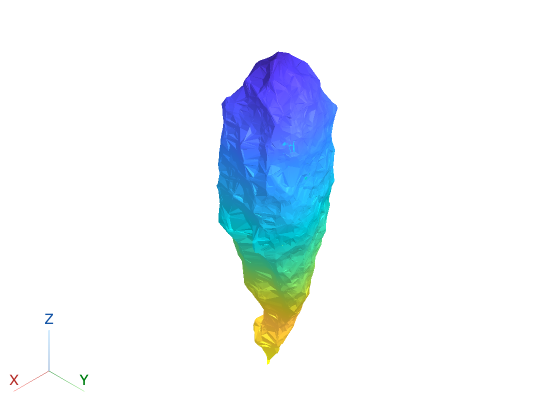

2. TB1_T2C11_fx.obj - 0
3. TB1_T2C11_mp.obj - 0


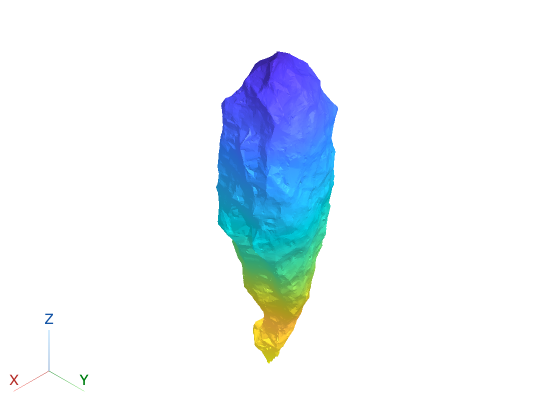

ans =   LinkProp with properties:

          Enabled: 'on'
    PropertyNames: {'CameraPosition'  'CameraZoom'}
          Targets: [1×3 Viewer3D]


dyingT.Properties.UserData.filePath = fullfile(paths.lysosome,"dyingT.mat");
dyingT.Properties.UserData.meshPath = paths.cellMesh;


dyingT.Type = categorical(dyingT.Type);
dyingT.Health = categorical(dyingT.Health);
type = dyingT.Type;
type(dyingT.Health=="early") = 'ed';
type(dyingT.Health=="late") = 'ld';
dyingT.PlotSort = categorical(type,{'IV','III','II','I','ld','ed'},'ordinal',true);

### Exclude TB2_TCdying rows from analysis

- They will be captured in the ***cellT*** dataset

la_tb2 = contains(dyCellMeshT.Cell,"TB2_TCdying");

       Cell        Type    Health    Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX 
    ___________    ____    ______    ______    ________    ___________    ______    ______    ______

    "TB1_T2C11"     II     early      "mp"        1            NaN        300.16    736.68    736.58

       Cell        Type    Health    Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX 
    ___________    ____    ______    ______    ________

dyingT(la_tb2,:) = [];

### save dyingT table

save(dyingT.Properties.UserData.filePath,"dyingT")

# Local Functions

## get all vertices

function dyVL = getAllDyingVL(paths, didT, loadT)

dyCellMeshRowExcerpt = 1×9 table
       Cell        Type    Health    Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX 
    ___________    ____    ______    ______    ________    ___________    ______    ______    ______

    "TB1_T2C11"     II     early      "mp"        -1            1         189.23    717.99    717.96


%GETALLVL all trace data identified in idT

dyCellMeshT = 15×9 table
         Cell          Type    Health     Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX 
    _______________    ____    _______    ______    ________    ___________    ______    ______    ______

    "TB2_TCdying01"    x       late        "mp"         1           NaN        149.89     403.6    403.03
    "TB2_TCdying02"    x       late        "mp"         1           NaN        249.22    457.08    456.91
    "TB3_TC01"         x       late        "mp"         1           NaN        246.54    446.93    446.92
    "TB3_TC02"         II      early       "mp"         1           NaN        797.71    943.65    967.71
    "TB3_TC03"         III     e

%   Analysis: Lysosome Analysis
% OUTPUT
%   - VL: vertices list table contains the x,y,z coordinates of the cells
%       and lysosome tracings


arguments
    paths struct % structure containing paths to the relevant folders
    didT table % id table contains manually entered information (either idT or didT)
    loadT table % table containing load last selections
end

dyVL = [];

for n = 1:height(loadT)
    load_last = loadT.Load_Last(n);
    series_path = fullfile(paths.reconstruct,loadT.Folder(n));
    fprintf('%d. %s.\n',n,loadT.Folder(n));

    [seriesT, traceT] = get_series_contents(series_path,load_last); % true input means load mat files instead

    la = didT.Folder == loadT.Folder(n);

    filter_str = didT.Object(la);

    fTL = filter_trace_list(seriesT,traceT, filter_str,true); % true means exact match
    fTL.Properties.Description = 'dying'; % modifies file name to keep projects separate

    % Load vl
    vl = get_verTCs(seriesT,fTL,load_last);

    img_mag = vl.Properties.UserData.img_mag;
    vl(:,["x","y","z"]) = varfun(@(x) x * img_mag,vl,InputVariables=["x","y","z"]); % convert to microns    

    %Concatenate
    dyVL = [dyVL; vl];
end

dyVL.Properties.VariableUnits(3:5) = repmat({'µm'},1,3);
dyVL.Properties.UserData.idT = didT;

dyVL.Properties.UserData.file = fullfile(paths.lysosome, "dyingVL.mat"); % same folder as live script
save(dyVL.Properties.UserData.file,"dyVL")
fprintf('dyVL saved as %s\n',dyVL.Properties.UserData.file)

end

% switch IDT.Properties.Description
%         case 'dying' %didT
%         filter_str = IDT.Object(la);
%         case 'lys' %idT
%         filter_str = [IDT.Cell(la); IDT.Lysosome(la)];
%     end

## get table

function T = get_table(dyingTableCSV)
opts2 = delimitedTextImportOptions("NumVariables", 8, "Encoding", "UTF-8");

% Specify range and delimiter
opts2.DataLines = [2, Inf];
opts2.Delimiter = ",";

% Specify column names and types
opts2.VariableNames = ["Cell", "Object", "Type", "Health", "TB", "Dataset", "Folder", "Mesh"];
opts2.VariableTypes = ["string", "string", "categorical", "categorical", "double", "categorical", "string", "double"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% Specify variable properties
opts2 = setvaropts(opts2, ["Cell", "Object"], "WhitespaceRule", "preserve");
opts2 = setvaropts(opts2, ["Cell", "Object", "Type", "Health"], "EmptyFieldRule", "auto");
opts2 = setvaropts(opts2, "TB", "TrimNonNumeric", true);
% opts2 = setvaropts(opts2, ["TB", "Dataset", "Folder"], "ThousandsSeparator", ",");

% Import the data
T = readtable(dyingTableCSV, opts2);
T.Properties.Description = 'dying';

% Clear temporary variables
end

## Generate Cell Meshes

Also calculates volumes for each mesh

function [dyCellMeshT] = genDyingCellMesh(dyVL,dyIDT,paths)
%GET_CELL_METRICS. Calculates the volume of each cell
% INPUT
%       - didT. Cell Object and ID table. Also contains Mesh column. 
%               Set to false if you want to recalculate the volume
% OUTPUTS: dcmT table contains calculated volumes for the meshes

arguments
    dyVL table % vertices list table
    dyIDT table % contains Cell Object and ID names.
    paths struct % contains project relevant paths
end

% suppress alpha shape warnings
id = 'MATLAB:alphaShape:DupPointsBasicWarnId';
warning('off',id);


% load previous dcmT table
if exist(fullfile(paths.cellMesh,"dyCellMeshT.mat"),'file') % start with meshT
    fprintf('dyCellMeshT file found and loaded. Using this table for the analysis.\n')
    load(fullfile(paths.cellMesh,"dyCellMeshT.mat"),"-mat","dyCellMeshT") % load dcmT
    % if ~isempty(options.ID2recalc)
    %     rows2recalc = ismember(dcmT.ID,options.ID2recalc);
    %     dcmT{rows2recalc,{'VolAS','VolMP','VolFX'}} = nan(height(meshT),3); % reset the volumes
    % end
    % count=height(dcmT);
else
    dyCellMeshT = table;
end

[lia, ~] = ismember(dyIDT.Cell, dyCellMeshT.Cell);

% Preallocate dcmT table or add new rows to pre-existing dcmT
if any(~lia) % any rows not found in dyCellMeshT?
    t = dyIDT(~lia,{'Cell','Type','Health'});
        % didT = sortrows(didT,["Type","Health"]);
    [~,ia] = unique(t.Cell);
    t = t(ia,:); % only unique Cell IDs

    count=height(t);
    t.Method = repmat("mp",count,1);
    t.Polarity = ones(count,1);
    t = [t array2table(nan(count,4),'VariableNames',["AlphaRadius","VolAS","VolMP","VolFX"])];

    dyCellMeshT = [dyCellMeshT; t]; % concatenate tables
end

% Calculate volumes of meshes 

rows2calc = find(isnan(dyCellMeshT.VolAS))'; % rows in dcmT that do not have a calculated volume
count = numel(rows2calc);

hwb = waitbar(0,"Please Wait");
for n=rows2calc

    cellID = dyCellMeshT.Cell(n); % capture current cell ID
    fprintf("Row %d. %s ",n,cellID)

    row_la = dyIDT.Cell == cellID; % find row in dyIDT to grab corresponding Object trace names          
    vl_la = ismember(dyVL.Object,dyIDT.Object(row_la)); % find the match cell object traces
    
    if ~any(vl_la)
        fprintf("not found.\n",n,cellID)
        continue
    else
        fprintf("found and meshed.\n")
    end

    vCell = (dyVL{vl_la,["x" "y" "z"]});
    vCell = realign_vCell(vCell); 

 % calculate alphaShape and then surface mesh object
    if isnan(dyCellMeshT.AlphaRadius(n))
        shp = alphaShape(vCell); % no alpha radius inputted - the default
    else
        shp = alphaShape(vCell,dyCellMeshT.AlphaRadius(n));
    end

    [volMP, volFX] = getWaterTightMesh(shp,cellID, paths);

    dyCellMeshT.VolAS(n) = shp.volume;
    dyCellMeshT.VolMP(n) = volMP;
    dyCellMeshT.VolFX(n) = volFX;
       
    waitbar(n/count, hwb,sprintf('%d. %s',n,cellID))
end

dyCellMeshT.Properties.UserData.filePath = fullfile(paths.cellMesh,"dcmT.mat");
dyCellMeshT.Properties.UserData.meshPath = paths.cellMesh;
dyCellMeshT.Properties.UserData.fdec = ["as" "mp" "fx"]; %as=alphaShape, mp=manifoldPlus, fx=meshFix
dyCellMeshT.Properties.UserData.ext = ".obj";
delete(hwb)

end

## Generate Single Cell Mesh

Specific to dying cells because of the different vl table

function [mt, srow] = generateSingleCellMesh(vl,dyIDT, dyCellMeshT,paths, cellName, Polarity, AlphaRadius)
%GENERATECELLMESH Generates meshes for the selected mesh.  Assumes VL contains lysosome structures

arguments
    vl table % vertices list
    dyIDT table % id Table (helps find the bits)
    dyCellMeshT table  % meshT table with info regarding cell to reconstruct
    paths struct % paths structure
    cellName {mustBeText}
    Polarity {mustBeNumeric,mustBeScalarOrEmpty}
    AlphaRadius {mustBeNumeric,mustBeScalarOrEmpty}
end

srow = find(dyCellMeshT.Cell==cellName);
mt = dyCellMeshT(srow,:);
disp(mt)
mt.Polarity = Polarity; % flip cell up
mt.AlphaRadius = AlphaRadius; % increase to close hole

cell_la = dyIDT.Cell == cellName; % returns cell names and bits
object_la = ismember(vl.Object,dyIDT.Object(cell_la));

vCell = (vl{object_la,["x" "y" "z"]});
vCell = realign_vCell(vCell);

% calculate alphaShape and then surface mesh object
if isnan(mt.AlphaRadius)
    shp = alphaShape(vCell); % no alpha radius inputted - the default
else
    shp = alphaShape(vCell,mt.AlphaRadius);
end
[volMP, volFX] = getWaterTightMesh(shp,mt.Cell, paths);
mt.VolAS = shp.volume;
mt.VolMP = volMP;
mt.VolFX = volFX;
disp(mt)
end

## Realign Vertices to Axes

function vCell = realign_vCell(vCell)
% transform vertices
vCell = vCell - mean(vCell);

[~,~,V]=svd(vCell,0); % Find the direction of most variance
vCell =  vCell * V;

% align to z-axis
% angl = 90 * polarity;
vCell = mmRotateSurfaceVertices(vCell,'y',90);

% rotate around z-axis
vCell = mmRotateSurfaceVertices(vCell,'z',90);
end